## Final Evaluation Setup

clear;
clc;
close all;

% ---------------------------------------------------------
% Locate project folder
% ---------------------------------------------------------

scriptPath = matlab.desktop.editor.getActiveFilename;
codeFolder = fileparts(scriptPath);
projectRoot = fileparts(codeFolder);

dataFolder = fullfile(projectRoot, 'data', 'flute');
audioFolder = fullfile(projectRoot, 'audio_output');
resultsFolder = fullfile(projectRoot, 'results');

% Create results folder if necessary
if ~exist(resultsFolder, 'dir')
    mkdir(resultsFolder);
end


%% Target Notes

notes = {'C4', 'E4', 'A4'};

f0Values = [260.79, 329.73, 442.25];


%% Reference Audio Files

referenceFiles = {
    fullfile(dataFolder, 'Flute.nonvib.ff.C4.stereo.aif')
    fullfile(dataFolder, 'Flute.nonvib.ff.E4.stereo.aif')
    fullfile(dataFolder, 'Flute.nonvib.ff.A4.stereo.aif')
};


%% Final Additive Synthesis Files

additiveFiles = {
    fullfile(audioFolder, 'Flute_C4_TimeVarying_Additive.wav')
    fullfile(audioFolder, 'Flute_E4_TimeVarying_Additive.wav')
    fullfile(audioFolder, 'Flute_A4_TimeVarying_Additive.wav')
};


%% Final FM Synthesis Files

fmFiles = {
    fullfile(audioFolder, 'Flute_C4_MultiStart_FM.wav')
    fullfile(audioFolder, 'Flute_E4_MultiStart_FM.wav')
    fullfile(audioFolder, 'Flute_A4_MultiStart_FM.wav')
};



fprintf('Final Evaluation File Check\n');

Final Evaluation File Check




allFilesAvailable = true;

for i = 1:length(notes)

    fprintf('\n%s:\n', notes{i});

    % Reference
    if isfile(referenceFiles{i})
        fprintf('Reference audio: FOUND\n');
    else
        fprintf('Reference audio: MISSING\n');
        allFilesAvailable = false;
    end

    % Additive
    if isfile(additiveFiles{i})
        fprintf('Additive audio:  FOUND\n');
    else
        fprintf('Additive audio:  MISSING\n');
        allFilesAvailable = false;
    end

    % FM
    if isfile(fmFiles{i})
        fprintf('FM audio:        FOUND\n');
    else
        fprintf('FM audio:        MISSING\n');
        allFilesAvailable = false;
    end

end


C4:


Reference audio: FOUND


Additive audio:  FOUND


FM audio:        FOUND



E4:


Reference audio: FOUND


Additive audio:  FOUND


FM audio:        FOUND



A4:


Reference audio: FOUND


Additive audio:  FOUND


FM audio:        FOUND




%% Final Check



if allFilesAvailable

    fprintf('All required audio files are available.\n');
    fprintf('Ready for final quantitative evaluation.\n');

else

    fprintf('Some required files are missing.\n');
    fprintf('Check the filenames shown above.\n');

end

All required audio files are available.


Ready for final quantitative evaluation.


###  Log-Spectral Distance Evaluation


% ---------------------------------------------------------
% Evaluation parameters
% ---------------------------------------------------------

windowLength = 2048;
overlapLength = 1536;
nfft = 4096;

maxEvalFrequency = 5000;

numNotes = length(notes);

additiveLSD = zeros(numNotes,1);
fmLSD = zeros(numNotes,1);


%% Calculate LSD for C4, E4 and A4

for i = 1:numNotes

    % -----------------------------------------------------
    % Load audio
    % -----------------------------------------------------

    [xRef, fsRef] = audioread(referenceFiles{i});
    [xAdd, fsAdd] = audioread(additiveFiles{i});
    [xFM, fsFM] = audioread(fmFiles{i});


    % -----------------------------------------------------
    % Convert to mono
    % -----------------------------------------------------

    if size(xRef,2) == 2
        xRef = mean(xRef,2);
    end

    if size(xAdd,2) == 2
        xAdd = mean(xAdd,2);
    end

    if size(xFM,2) == 2
        xFM = mean(xFM,2);
    end


    % -----------------------------------------------------
    % Match sampling rates
    % -----------------------------------------------------

    if fsAdd ~= fsRef
        xAdd = resample(xAdd, fsRef, fsAdd);
    end

    if fsFM ~= fsRef
        xFM = resample(xFM, fsRef, fsFM);
    end

    fs = fsRef;


    % -----------------------------------------------------
    % Match signal lengths
    % -----------------------------------------------------

    minLength = min( ...
        [length(xRef), ...
         length(xAdd), ...
         length(xFM)]);

    xRef = xRef(1:minLength);
    xAdd = xAdd(1:minLength);
    xFM  = xFM(1:minLength);


    % -----------------------------------------------------
    % Normalise signals
    % -----------------------------------------------------

    if max(abs(xRef)) > 0
        xRef = xRef / max(abs(xRef));
    end

    if max(abs(xAdd)) > 0
        xAdd = xAdd / max(abs(xAdd));
    end

    if max(abs(xFM)) > 0
        xFM = xFM / max(abs(xFM));
    end


    % -----------------------------------------------------
    % STFT
    % -----------------------------------------------------

    [Sref, F, ~] = spectrogram( ...
        xRef, ...
        hann(windowLength), ...
        overlapLength, ...
        nfft, ...
        fs);

    [Sadd, ~, ~] = spectrogram( ...
        xAdd, ...
        hann(windowLength), ...
        overlapLength, ...
        nfft, ...
        fs);

    [Sfm, ~, ~] = spectrogram( ...
        xFM, ...
        hann(windowLength), ...
        overlapLength, ...
        nfft, ...
        fs);


    % -----------------------------------------------------
    % Restrict evaluation to 0-5 kHz
    % -----------------------------------------------------

    freqMask = F <= maxEvalFrequency;

    refMag = abs(Sref(freqMask,:));
    addMag = abs(Sadd(freqMask,:));
    fmMag  = abs(Sfm(freqMask,:));


    % -----------------------------------------------------
    % Convert to log magnitude
    % -----------------------------------------------------

    epsilon = 1e-8;

    refLog = 20 * log10(refMag + epsilon);
    addLog = 20 * log10(addMag + epsilon);
    fmLog  = 20 * log10(fmMag  + epsilon);


    % -----------------------------------------------------
    % Frame-wise LSD
    % -----------------------------------------------------

    additiveFrameLSD = sqrt( ...
        mean( ...
        (refLog - addLog).^2, ...
        1));

    fmFrameLSD = sqrt( ...
        mean( ...
        (refLog - fmLog).^2, ...
        1));


    % -----------------------------------------------------
    % Mean LSD for each note
    % -----------------------------------------------------

    additiveLSD(i) = mean(additiveFrameLSD);
    fmLSD(i) = mean(fmFrameLSD);

end


%% Results Table

LSDTable = table( ...
    notes', ...
    additiveLSD, ...
    fmLSD, ...
    'VariableNames', ...
    {'Note', ...
     'Additive_LSD_dB', ...
     'FM_LSD_dB'});

LSDTable

LSDTable = 3×3 table
     Note     Additive_LSD_dB    FM_LSD_dB
    ______    _______________    _________

    {'C4'}        42.081          23.157  
    {'E4'}        36.227          25.412  
    {'A4'}        27.133          25.216  

	使用 Copilot 获取洞察




%% Mean Results

meanAdditiveLSD = mean(additiveLSD);
meanFMLSD = mean(fmLSD);

LSDMeanTable = table( ...
    meanAdditiveLSD, ...
    meanFMLSD, ...
    'VariableNames', ...
    {'Mean_Additive_LSD_dB', ...
     'Mean_FM_LSD_dB'});

LSDMeanTable

LSDMeanTable = 1×2 table
    Mean_Additive_LSD_dB    Mean_FM_LSD_dB
    ____________________    ______________

           35.147               24.595    

	使用 Copilot 获取洞察


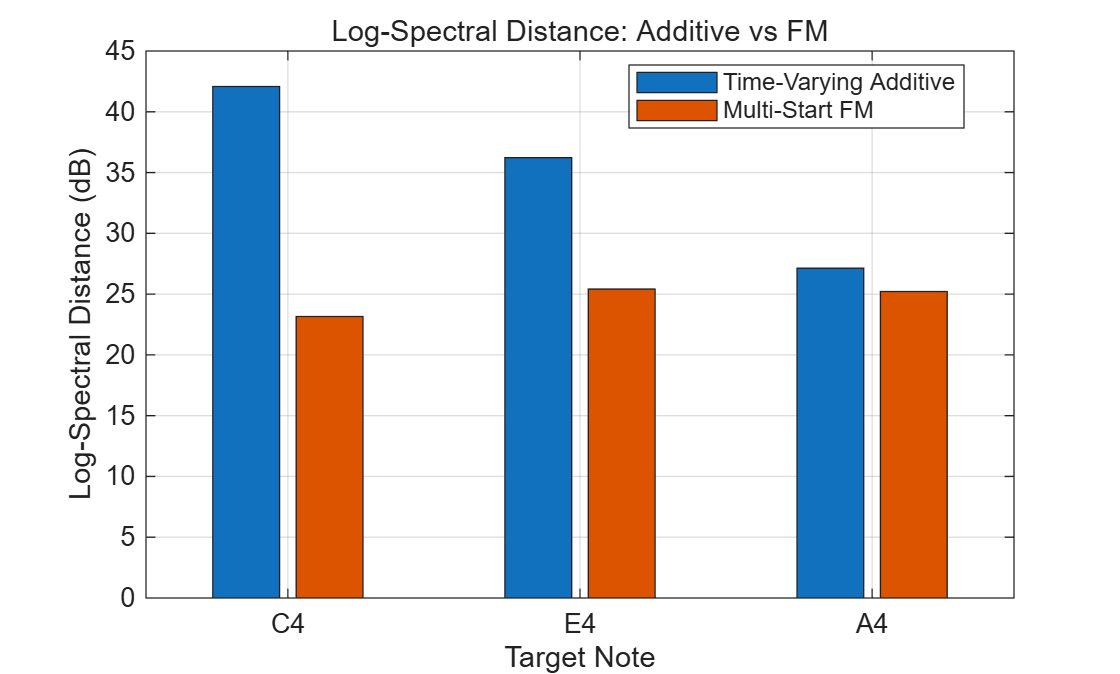



%% LSD Comparison Figure

figure;

bar([additiveLSD, fmLSD]);

xlabel('Target Note');
ylabel('Log-Spectral Distance (dB)');

title('Log-Spectral Distance: Additive vs FM');

xticks(1:numNotes);
xticklabels(notes);

legend( ...
    'Time-Varying Additive', ...
    'Multi-Start FM', ...
    'Location', ...
    'best');

grid on;


%% Save Results

csvFile = fullfile( ...
    resultsFolder, ...
    'Final_LSD_Results.csv');

writetable( ...
    LSDTable, ...
    csvFile);


meanCsvFile = fullfile( ...
    resultsFolder, ...
    'Final_LSD_Mean_Results.csv');

writetable( ...
    LSDMeanTable, ...
    meanCsvFile);


figureFile = fullfile( ...
    resultsFolder, ...
    'Final_LSD_Comparison.png');

exportgraphics( ...
    gcf, ...
    figureFile, ...
    'Resolution', ...
    300);

### Multi-Resolution STFT Error Evaluation


% ---------------------------------------------------------
% Three STFT resolutions
% Short / medium / long windows
% ---------------------------------------------------------

windowLengths = [512, 2048, 8192];
nfftValues    = [1024, 4096, 16384];

maxEvalFrequency = 5000;

numNotes = length(notes);
numResolutions = length(windowLengths);

% Store errors for each resolution
additiveMRSTFT = zeros(numNotes, numResolutions);
fmMRSTFT       = zeros(numNotes, numResolutions);


%% Calculate Multi-Resolution STFT Error

for i = 1:numNotes

    % -----------------------------------------------------
    % Load audio
    % -----------------------------------------------------

    [xRef, fsRef] = audioread(referenceFiles{i});
    [xAdd, fsAdd] = audioread(additiveFiles{i});
    [xFM, fsFM]   = audioread(fmFiles{i});


    % -----------------------------------------------------
    % Convert to mono
    % -----------------------------------------------------

    if size(xRef,2) == 2
        xRef = mean(xRef,2);
    end

    if size(xAdd,2) == 2
        xAdd = mean(xAdd,2);
    end

    if size(xFM,2) == 2
        xFM = mean(xFM,2);
    end


    % -----------------------------------------------------
    % Match sampling rates
    % -----------------------------------------------------

    if fsAdd ~= fsRef
        xAdd = resample(xAdd, fsRef, fsAdd);
    end

    if fsFM ~= fsRef
        xFM = resample(xFM, fsRef, fsFM);
    end

    fs = fsRef;


    % -----------------------------------------------------
    % Match signal lengths
    % -----------------------------------------------------

    minLength = min( ...
        [length(xRef), ...
         length(xAdd), ...
         length(xFM)]);

    xRef = xRef(1:minLength);
    xAdd = xAdd(1:minLength);
    xFM  = xFM(1:minLength);


    % -----------------------------------------------------
    % Normalise signals
    % -----------------------------------------------------

    if max(abs(xRef)) > 0
        xRef = xRef / max(abs(xRef));
    end

    if max(abs(xAdd)) > 0
        xAdd = xAdd / max(abs(xAdd));
    end

    if max(abs(xFM)) > 0
        xFM = xFM / max(abs(xFM));
    end


    % -----------------------------------------------------
    % Evaluate three STFT resolutions
    % -----------------------------------------------------

    for r = 1:numResolutions

        windowLength = windowLengths(r);

        % 75% overlap
        overlapLength = round(0.75 * windowLength);

        nfft = nfftValues(r);


        % Reference STFT
        [Sref, F, ~] = spectrogram( ...
            xRef, ...
            hann(windowLength), ...
            overlapLength, ...
            nfft, ...
            fs);


        % Additive STFT
        [Sadd, ~, ~] = spectrogram( ...
            xAdd, ...
            hann(windowLength), ...
            overlapLength, ...
            nfft, ...
            fs);


        % FM STFT
        [Sfm, ~, ~] = spectrogram( ...
            xFM, ...
            hann(windowLength), ...
            overlapLength, ...
            nfft, ...
            fs);


        % -------------------------------------------------
        % Restrict evaluation to 0-5 kHz
        % -------------------------------------------------

        freqMask = F <= maxEvalFrequency;

        refMag = abs(Sref(freqMask,:));
        addMag = abs(Sadd(freqMask,:));
        fmMag  = abs(Sfm(freqMask,:));


        % -------------------------------------------------
        % Normalised spectral magnitude error
        % -------------------------------------------------

        epsilon = 1e-12;

        referenceEnergy = ...
            norm(refMag, 'fro') + epsilon;

        additiveMRSTFT(i,r) = ...
            norm(refMag - addMag, 'fro') / ...
            referenceEnergy;

        fmMRSTFT(i,r) = ...
            norm(refMag - fmMag, 'fro') / ...
            referenceEnergy;

    end

end


%% Combined Multi-Resolution Error

% Mean across short, medium and long resolutions

additiveMRMean = mean(additiveMRSTFT, 2);
fmMRMean       = mean(fmMRSTFT, 2);


%% Detailed Results Table

MRSTFTTable = table( ...
    notes', ...
    additiveMRSTFT(:,1), ...
    additiveMRSTFT(:,2), ...
    additiveMRSTFT(:,3), ...
    additiveMRMean, ...
    fmMRSTFT(:,1), ...
    fmMRSTFT(:,2), ...
    fmMRSTFT(:,3), ...
    fmMRMean, ...
    'VariableNames', ...
    { ...
    'Note', ...
    'Additive_Short', ...
    'Additive_Medium', ...
    'Additive_Long', ...
    'Additive_MR_Mean', ...
    'FM_Short', ...
    'FM_Medium', ...
    'FM_Long', ...
    'FM_MR_Mean' ...
    });

MRSTFTTable

MRSTFTTable = 3×9 table
     Note     Additive_Short    Additive_Medium    Additive_Long    Additive_MR_Mean    FM_Short    FM_Medium    FM_Long    FM_MR_Mean
    ______    ______________    _______________    _____________    ________________    ________    _________    _______    __________

    {'C4'}        0.16245           0.16137           0.20532           0.17638          1.3877      1.6608      1.7786        1.609  
    {'E4'}       0.058469           0.08241           0.22032            0.1204          1.5581      1.8282      1.8661       1.7508  
    {'A4'}        0.04633           0.15004           0.45973            0.2187          1.4248      1.6676      1.6882       1.5935  

	使用 Copilot 获取洞察




%% Overall Mean Results

meanAdditiveMRSTFT = mean(additiveMRMean);
meanFMMRSTFT       = mean(fmMRMean);

MRSTFTMeanTable = table( ...
    meanAdditiveMRSTFT, ...
    meanFMMRSTFT, ...
    'VariableNames', ...
    { ...
    'Mean_Additive_MRSTFT_Error', ...
    'Mean_FM_MRSTFT_Error' ...
    });

MRSTFTMeanTable

MRSTFTMeanTable = 1×2 table
    Mean_Additive_MRSTFT_Error    Mean_FM_MRSTFT_Error
    __________________________    ____________________

             0.17183                     1.6511       

	使用 Copilot 获取洞察


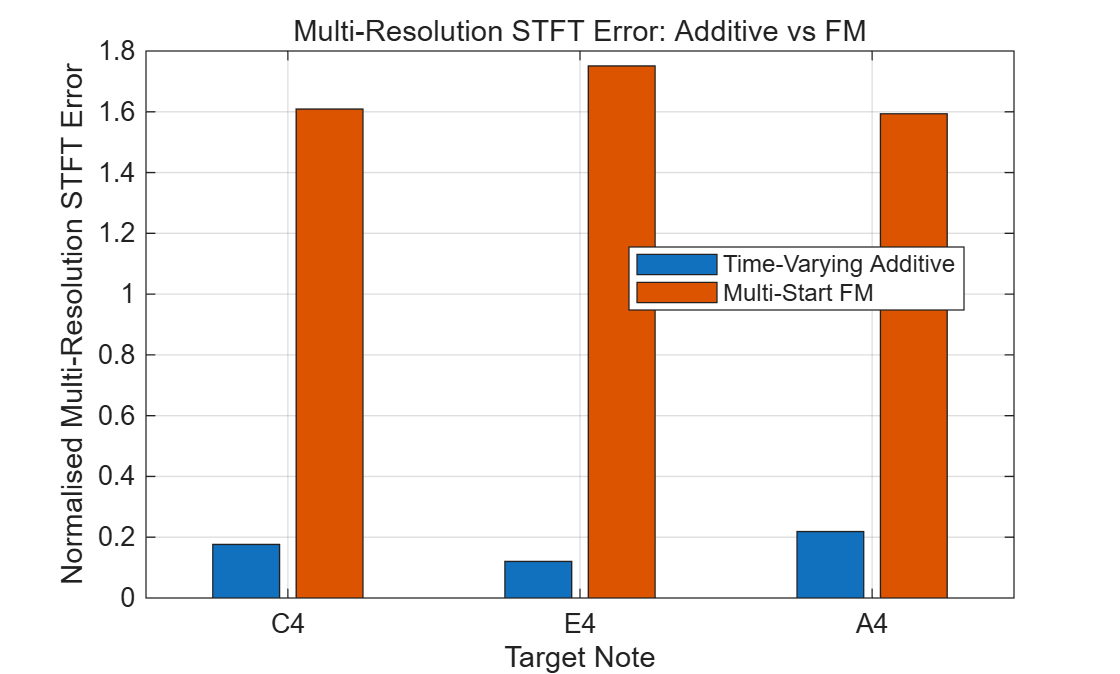



%% Multi-Resolution STFT Comparison Figure

figure;

bar([additiveMRMean, fmMRMean]);

xlabel('Target Note');
ylabel('Normalised Multi-Resolution STFT Error');

title('Multi-Resolution STFT Error: Additive vs FM');

xticks(1:numNotes);
xticklabels(notes);

legend( ...
    'Time-Varying Additive', ...
    'Multi-Start FM', ...
    'Location', ...
    'best');

grid on;


%% Save Results

csvFile = fullfile( ...
    resultsFolder, ...
    'Final_MRSTFT_Results.csv');

writetable( ...
    MRSTFTTable, ...
    csvFile);


meanCsvFile = fullfile( ...
    resultsFolder, ...
    'Final_MRSTFT_Mean_Results.csv');

writetable( ...
    MRSTFTMeanTable, ...
    meanCsvFile);


figureFile = fullfile( ...
    resultsFolder, ...
    'Final_MRSTFT_Comparison.png');

exportgraphics( ...
    gcf, ...
    figureFile, ...
    'Resolution', ...
    300);

### Harmonic Amplitude Error Evaluation


% ---------------------------------------------------------
% Evaluation settings
% ---------------------------------------------------------

numHarmonics = 10;
harmonicSearchRangeHz = 20;

numNotes = length(notes);

referenceHarmonics = zeros(numNotes, numHarmonics);
additiveHarmonics  = zeros(numNotes, numHarmonics);
fmHarmonics        = zeros(numNotes, numHarmonics);

additiveHarmonicError = zeros(numNotes,1);
fmHarmonicError       = zeros(numNotes,1);


%% Calculate Harmonic Amplitude Error

for i = 1:numNotes

    % -----------------------------------------------------
    % Load audio
    % -----------------------------------------------------

    [xRef, fsRef] = audioread(referenceFiles{i});
    [xAdd, fsAdd] = audioread(additiveFiles{i});
    [xFM, fsFM]   = audioread(fmFiles{i});


    % -----------------------------------------------------
    % Convert to mono
    % -----------------------------------------------------

    if size(xRef,2) == 2
        xRef = mean(xRef,2);
    end

    if size(xAdd,2) == 2
        xAdd = mean(xAdd,2);
    end

    if size(xFM,2) == 2
        xFM = mean(xFM,2);
    end


    % -----------------------------------------------------
    % Match sampling rates
    % -----------------------------------------------------

    if fsAdd ~= fsRef
        xAdd = resample(xAdd, fsRef, fsAdd);
    end

    if fsFM ~= fsRef
        xFM = resample(xFM, fsRef, fsFM);
    end

    fs = fsRef;


    % -----------------------------------------------------
    % Match signal lengths
    % -----------------------------------------------------

    minLength = min( ...
        [length(xRef), ...
         length(xAdd), ...
         length(xFM)]);

    xRef = xRef(1:minLength);
    xAdd = xAdd(1:minLength);
    xFM  = xFM(1:minLength);


    % -----------------------------------------------------
    % Normalise waveform amplitude
    % -----------------------------------------------------

    if max(abs(xRef)) > 0
        xRef = xRef / max(abs(xRef));
    end

    if max(abs(xAdd)) > 0
        xAdd = xAdd / max(abs(xAdd));
    end

    if max(abs(xFM)) > 0
        xFM = xFM / max(abs(xFM));
    end


    % -----------------------------------------------------
    % FFT with zero padding
    % -----------------------------------------------------

    signalLength = length(xRef);

    nfftHarmonic = ...
        4 * 2^nextpow2(signalLength);

    analysisWindow = hann(signalLength);


    Xref = fft( ...
        xRef .* analysisWindow, ...
        nfftHarmonic);

    Xadd = fft( ...
        xAdd .* analysisWindow, ...
        nfftHarmonic);

    Xfm = fft( ...
        xFM .* analysisWindow, ...
        nfftHarmonic);


    % One-sided spectra

    halfLength = floor(nfftHarmonic/2) + 1;

    refSpectrum = abs(Xref(1:halfLength));
    addSpectrum = abs(Xadd(1:halfLength));
    fmSpectrum  = abs(Xfm(1:halfLength));

    frequencyAxis = ...
        (0:halfLength-1)' * ...
        fs / nfftHarmonic;


    % -----------------------------------------------------
    % Extract harmonic peak amplitudes
    % -----------------------------------------------------

    f0 = f0Values(i);

    for h = 1:numHarmonics

        targetFrequency = h * f0;

        searchMask = ...
            frequencyAxis >= ...
            (targetFrequency - harmonicSearchRangeHz) & ...
            frequencyAxis <= ...
            (targetFrequency + harmonicSearchRangeHz);


        referenceHarmonics(i,h) = ...
            max(refSpectrum(searchMask));

        additiveHarmonics(i,h) = ...
            max(addSpectrum(searchMask));

        fmHarmonics(i,h) = ...
            max(fmSpectrum(searchMask));

    end


    % -----------------------------------------------------
    % Convert to relative harmonic distributions
    % -----------------------------------------------------

    refHarmonicVector = referenceHarmonics(i,:);
    addHarmonicVector = additiveHarmonics(i,:);
    fmHarmonicVector  = fmHarmonics(i,:);


    if sum(refHarmonicVector) > 0
        refHarmonicVector = ...
            refHarmonicVector / ...
            sum(refHarmonicVector);
    end

    if sum(addHarmonicVector) > 0
        addHarmonicVector = ...
            addHarmonicVector / ...
            sum(addHarmonicVector);
    end

    if sum(fmHarmonicVector) > 0
        fmHarmonicVector = ...
            fmHarmonicVector / ...
            sum(fmHarmonicVector);
    end


    % Save normalised distributions

    referenceHarmonics(i,:) = refHarmonicVector;
    additiveHarmonics(i,:)  = addHarmonicVector;
    fmHarmonics(i,:)        = fmHarmonicVector;


    % -----------------------------------------------------
    % Normalised RMSE of harmonic amplitudes
    % -----------------------------------------------------

    additiveHarmonicError(i) = sqrt( ...
        mean( ...
        (refHarmonicVector - ...
         addHarmonicVector).^2));

    fmHarmonicError(i) = sqrt( ...
        mean( ...
        (refHarmonicVector - ...
         fmHarmonicVector).^2));

end


%% Harmonic Error Results Table

HarmonicErrorTable = table( ...
    notes', ...
    additiveHarmonicError, ...
    fmHarmonicError, ...
    'VariableNames', ...
    { ...
    'Note', ...
    'Additive_Harmonic_Error', ...
    'FM_Harmonic_Error' ...
    });

HarmonicErrorTable

HarmonicErrorTable = 3×3 table
     Note     Additive_Harmonic_Error    FM_Harmonic_Error
    ______    _______________________    _________________

    {'C4'}           0.010463                 0.28351     
    {'E4'}           0.029305                 0.21921     
    {'A4'}           0.017024                 0.27437     

	使用 Copilot 获取洞察




%% Mean Harmonic Error

meanAdditiveHarmonicError = ...
    mean(additiveHarmonicError);

meanFMHarmonicError = ...
    mean(fmHarmonicError);

HarmonicMeanTable = table( ...
    meanAdditiveHarmonicError, ...
    meanFMHarmonicError, ...
    'VariableNames', ...
    { ...
    'Mean_Additive_Harmonic_Error', ...
    'Mean_FM_Harmonic_Error' ...
    });

HarmonicMeanTable

HarmonicMeanTable = 1×2 table
    Mean_Additive_Harmonic_Error    Mean_FM_Harmonic_Error
    ____________________________    ______________________

              0.018931                     0.25903        

	使用 Copilot 获取洞察


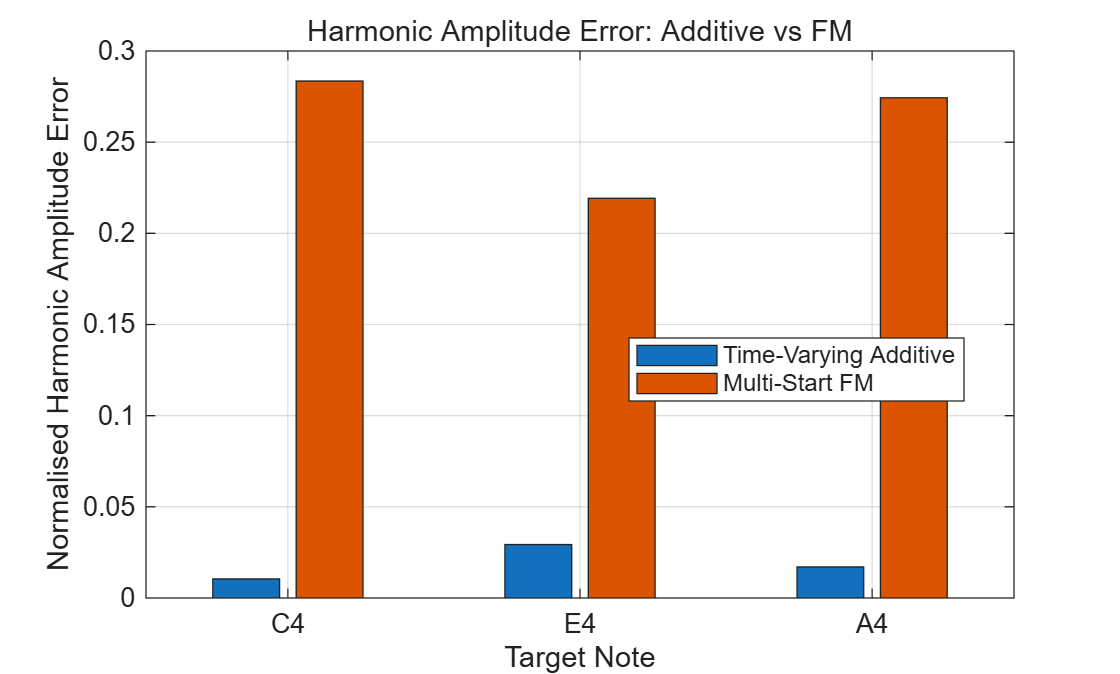



%% Harmonic Error Comparison Figure

figure;

bar([ ...
    additiveHarmonicError, ...
    fmHarmonicError]);

xlabel('Target Note');

ylabel( ...
    'Normalised Harmonic Amplitude Error');

title( ...
    'Harmonic Amplitude Error: Additive vs FM');

xticks(1:numNotes);
xticklabels(notes);

legend( ...
    'Time-Varying Additive', ...
    'Multi-Start FM', ...
    'Location', ...
    'best');

grid on;


%% Save Results

csvFile = fullfile( ...
    resultsFolder, ...
    'Final_Harmonic_Error_Results.csv');

writetable( ...
    HarmonicErrorTable, ...
    csvFile);


meanCsvFile = fullfile( ...
    resultsFolder, ...
    'Final_Harmonic_Error_Mean_Results.csv');

writetable( ...
    HarmonicMeanTable, ...
    meanCsvFile);


figureFile = fullfile( ...
    resultsFolder, ...
    'Final_Harmonic_Error_Comparison.png');

exportgraphics( ...
    gcf, ...
    figureFile, ...
    'Resolution', ...
    300);

### Temporal-Envelope Error Evaluation


% ---------------------------------------------------------
% Evaluation settings
% ---------------------------------------------------------

envelopeWindowSeconds = 0.02;

numNotes = length(notes);

additiveEnvelopeError = zeros(numNotes,1);
fmEnvelopeError       = zeros(numNotes,1);


%% Calculate Temporal-Envelope Error

for i = 1:numNotes

    % -----------------------------------------------------
    % Load audio
    % -----------------------------------------------------

    [xRef, fsRef] = audioread(referenceFiles{i});
    [xAdd, fsAdd] = audioread(additiveFiles{i});
    [xFM, fsFM]   = audioread(fmFiles{i});


    % -----------------------------------------------------
    % Convert to mono
    % -----------------------------------------------------

    if size(xRef,2) == 2
        xRef = mean(xRef,2);
    end

    if size(xAdd,2) == 2
        xAdd = mean(xAdd,2);
    end

    if size(xFM,2) == 2
        xFM = mean(xFM,2);
    end


    % -----------------------------------------------------
    % Match sampling rates
    % -----------------------------------------------------

    if fsAdd ~= fsRef
        xAdd = resample(xAdd, fsRef, fsAdd);
    end

    if fsFM ~= fsRef
        xFM = resample(xFM, fsRef, fsFM);
    end

    fs = fsRef;


    % -----------------------------------------------------
    % Match signal lengths
    % -----------------------------------------------------

    minLength = min( ...
        [length(xRef), ...
         length(xAdd), ...
         length(xFM)]);

    xRef = xRef(1:minLength);
    xAdd = xAdd(1:minLength);
    xFM  = xFM(1:minLength);


    % -----------------------------------------------------
    % Normalise waveform amplitudes
    % -----------------------------------------------------

    if max(abs(xRef)) > 0
        xRef = xRef / max(abs(xRef));
    end

    if max(abs(xAdd)) > 0
        xAdd = xAdd / max(abs(xAdd));
    end

    if max(abs(xFM)) > 0
        xFM = xFM / max(abs(xFM));
    end


    % -----------------------------------------------------
    % Extract RMS temporal envelopes
    % -----------------------------------------------------

    envelopeWindow = ...
        round(envelopeWindowSeconds * fs);

    refEnvelope = sqrt( ...
        movmean(xRef.^2, envelopeWindow));

    addEnvelope = sqrt( ...
        movmean(xAdd.^2, envelopeWindow));

    fmEnvelope = sqrt( ...
        movmean(xFM.^2, envelopeWindow));


    % -----------------------------------------------------
    % Normalise envelopes
    % -----------------------------------------------------

    if max(refEnvelope) > 0
        refEnvelope = ...
            refEnvelope / max(refEnvelope);
    end

    if max(addEnvelope) > 0
        addEnvelope = ...
            addEnvelope / max(addEnvelope);
    end

    if max(fmEnvelope) > 0
        fmEnvelope = ...
            fmEnvelope / max(fmEnvelope);
    end


    % -----------------------------------------------------
    % Envelope RMSE
    % -----------------------------------------------------

    additiveEnvelopeError(i) = sqrt( ...
        mean( ...
        (refEnvelope - addEnvelope).^2));

    fmEnvelopeError(i) = sqrt( ...
        mean( ...
        (refEnvelope - fmEnvelope).^2));

end


%% Temporal-Envelope Results Table

EnvelopeErrorTable = table( ...
    notes', ...
    additiveEnvelopeError, ...
    fmEnvelopeError, ...
    'VariableNames', ...
    { ...
    'Note', ...
    'Additive_Envelope_Error', ...
    'FM_Envelope_Error' ...
    });

EnvelopeErrorTable

EnvelopeErrorTable = 3×3 table
     Note     Additive_Envelope_Error    FM_Envelope_Error
    ______    _______________________    _________________

    {'C4'}           0.029439                 0.014879    
    {'E4'}           0.018582                 0.018455    
    {'A4'}           0.012416                0.0061754    

	使用 Copilot 获取洞察




%% Mean Temporal-Envelope Error

meanAdditiveEnvelopeError = ...
    mean(additiveEnvelopeError);

meanFMEnvelopeError = ...
    mean(fmEnvelopeError);

EnvelopeMeanTable = table( ...
    meanAdditiveEnvelopeError, ...
    meanFMEnvelopeError, ...
    'VariableNames', ...
    { ...
    'Mean_Additive_Envelope_Error', ...
    'Mean_FM_Envelope_Error' ...
    });

EnvelopeMeanTable

EnvelopeMeanTable = 1×2 table
    Mean_Additive_Envelope_Error    Mean_FM_Envelope_Error
    ____________________________    ______________________

              0.020146                     0.01317        

	使用 Copilot 获取洞察


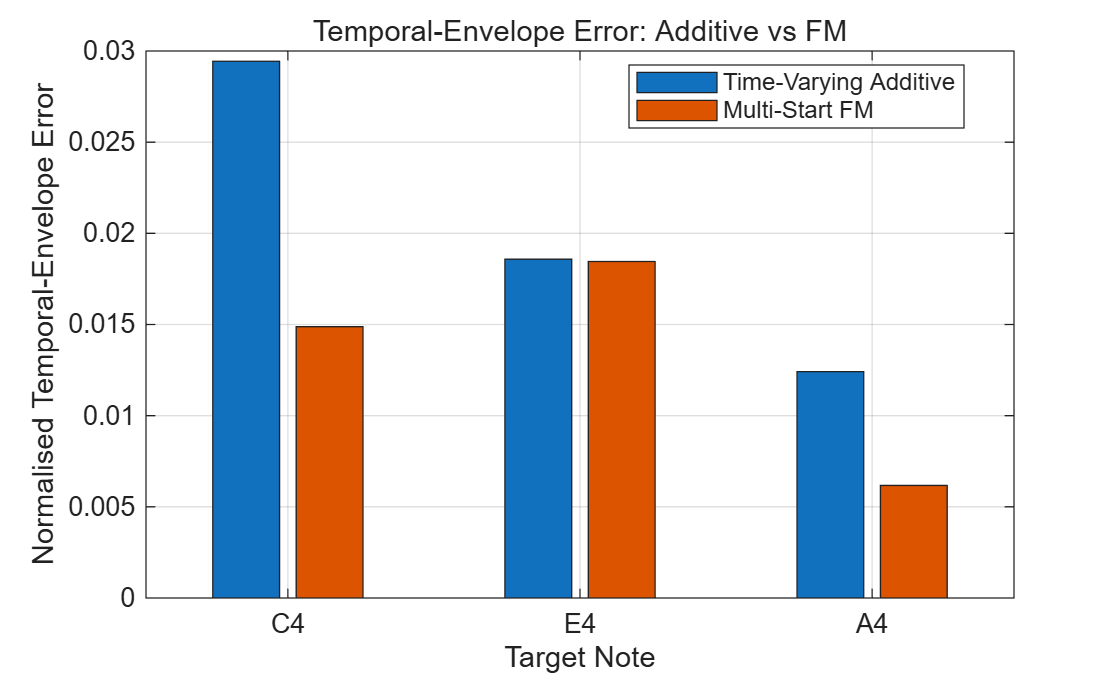



%% Temporal-Envelope Error Comparison Figure

figure;

bar([ ...
    additiveEnvelopeError, ...
    fmEnvelopeError]);

xlabel('Target Note');

ylabel('Normalised Temporal-Envelope Error');

title( ...
    'Temporal-Envelope Error: Additive vs FM');

xticks(1:numNotes);
xticklabels(notes);

legend( ...
    'Time-Varying Additive', ...
    'Multi-Start FM', ...
    'Location', ...
    'best');

grid on;


%% Save Results

csvFile = fullfile( ...
    resultsFolder, ...
    'Final_Envelope_Error_Results.csv');

writetable( ...
    EnvelopeErrorTable, ...
    csvFile);


meanCsvFile = fullfile( ...
    resultsFolder, ...
    'Final_Envelope_Error_Mean_Results.csv');

writetable( ...
    EnvelopeMeanTable, ...
    meanCsvFile);


figureFile = fullfile( ...
    resultsFolder, ...
    'Final_Envelope_Error_Comparison.png');

exportgraphics( ...
    gcf, ...
    figureFile, ...
    'Resolution', ...
    300);